**Problem 8.2 - 8.3  - The Tool Life Experiment**

Step 6.1. Import data

Levels raised to the number of factors, $l^f = 2^3 = 8 $ 

dFF3 = fullfact([2 2 2]) % fullfact is a MATLAB function that will 

dFF3 =      1     1     1
     2     1     1
     1     2     1
     2     2     1
     1     1     2
     2     1     2
     1     2     2
     2     2     2


% generate the full-factorial design test matrix
% Also use F1 on your keyboard after the function nameto access 
% help documentation
% The 1s and 2s represent the low level setting and 
% high level setting, respectively
% Each row represents a treatment combination
% Each column represents a factor
% For example, the first row which has all 1s means that every
% factor is set to the low setting


% Replace 1s and 2s with -1s and +1s, respectively, to code the design.
% Initialize array to hold coded variables
dFF3c = nan; % nan = Not a Number
% Repetition structure
for i = 1:length(dFF3(:,1)) % From one to number of number of rows in column 1
    for j = 1:length(dFF3(1,:))
        if dFF3(i,j) == 1
            dFF3c(i,j) = -1;
        else
            dFF3c(i,j) = 1;
        end
    end
end

dFF3c

dFF3c =     -1    -1    -1
     1    -1    -1
    -1     1    -1
     1     1    -1
    -1    -1     1
     1    -1     1
    -1     1     1
     1     1     1



% Factors
f1 = dFF3c(:,1) % Factor Cutting speed

f1 =     -1
     1
    -1
     1
    -1
     1
    -1
     1


f2 = dFF3c(:,2); % Factor Metal hardness, the ; supresses the output
f3 = dFF3c(:,3); % Factor Cutting angle
% Table to hold factor levels
tbl82 = table(f1,f2,f3,'VariableNames',{'Cutting Speed', ...
    'Metal Hardness','Cutting Angle'})

tbl82 = 8×3 table
    Cutting Speed    Metal Hardness    Cutting Angle
    _____________    ______________    _____________

         -1                -1               -1      
          1                -1               -1      
         -1                 1               -1      
          1                 1               -1      
         -1                -1                1      
          1                -1                1      
         -1                 1                1      
          1                 1                1      


Step 6.2 Response column(s)

tlife1 = [221;325;354;552;440;406;605;392]

tlife1 =    221
   325
   354
   552
   440
   406
   605
   392


tlife2 = [311;435;348;472;453;377;500;419]

tlife2 =    311
   435
   348
   472
   453
   377
   500
   419


% Table to hold replicates
tbl821 = table(tlife1,tlife2,'VariableNames',{'Replicate1','Replicate2'})

tbl821 = 8×2 table
    Replicate1    Replicate2
    __________    __________

       221           311    
       325           435    
       354           348    
       552           472    
       440           453    
       406           377    
       605           500    
       392           419    


% Replicates vector
rtlife = [tlife1;tlife2]

rtlife =    221
   325
   354
   552
   440
   406
   605
   392
   311
   435


Step 6.3 Examine data graphically

% Create a treatment cell array
treat = {'(1)';'a';'b';'ab';'c';'ac';'bc';'abc'}

treat = 8×1 cell array
    {'(1)'}
    {'a'  }
    {'b'  }
    {'ab' }
    {'c'  }
    {'ac' }
    {'bc' }
    {'abc'}


% Create a grouping variable
gtreat = [treat; treat]

gtreat = 16×1 cell array
    {'(1)'}
    {'a'  }
    {'b'  }
    {'ab' }
    {'c'  }
    {'ac' }
    {'bc' }
    {'abc'}
    {'(1)'}
    {'a'  }
    {'b'  }
    {'ab' }
    {'c'  }
    {'ac' }
    {'bc' }
    {'abc'}


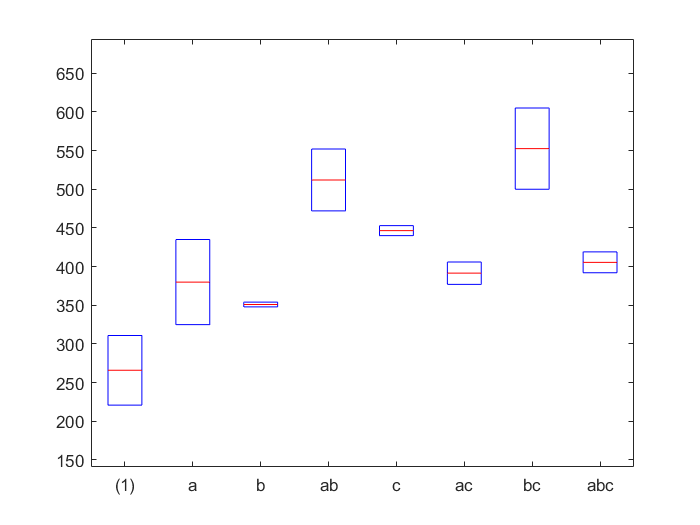

boxplot(rtlife,gtreat)

%% CLASS: Make some kind of observation of the box plot and comment on your findings. :)

Step 6.4 Create fitted model

The regression model

Create a table to hold the DOE test matrix and the response variables.

tbl822 = table([f1;f1],[f2;f2],[f3;f3],[tlife1;tlife2], ...
    'VariableNames',{'CuttingSpeed','MetalHardness','CuttingAngle', ...
    'ToolLife'})

tbl822 = 16×4 table
    CuttingSpeed    MetalHardness    CuttingAngle    ToolLife
    ____________    _____________    ____________    ________

         -1              -1               -1           221   
          1              -1               -1           325   
         -1               1               -1           354   
          1               1               -1           552   
         -1              -1                1           440   
          1              -1                1           406   
         -1               1                1           605   
          1               1                1           392   
         -1              -1               -1           311   
          1              -1               -1           435   
         -1               1               -1           348   
          1               1          

Linear regression model

Recall: Regression models describe the relationship between a response (output) variable, and one or more predictor (input variables).

mdl = fitlm(tbl822,'ToolLife ~ CuttingSpeed + MetalHardness + CuttingAngle')

mdl = Linear regression model:
    ToolLife ~ 1 + CuttingSpeed + MetalHardness + CuttingAngle

Estimated Coefficients:
                     Estimate     SE       tStat       pValue  
                     ________    _____    _______    __________

    (Intercept)       413.13     20.95     19.719    1.6449e-10
    CuttingSpeed       9.125     20.95    0.43556       0.67089
    MetalHardness     42.125     20.95     2.0107      0.067375
    CuttingAngle      35.875     20.95     1.7124       0.11252


Number of observations: 16, Error degrees of freedom: 12
Root Mean Squared Error: 83.8
R-squared: 0.374,  Adjusted R-Squared: 0.217
F-statistic vs. constant model: 2.39, p-value = 0.12


$$ToolLife = 413.13 + 9.125x_{CuttingSpeed} + 42.125x_{MetalHardness}+35.875x_{CuttingAngle}+20.95$$


Is this it?

Let's talk **interactions.**

- Interactions occur when two 'interact' to have an effect on the response, when they don't *necessarily* have an effect on an individual basis.

mdl2 = fitlm(tbl822,'ToolLife ~ CuttingSpeed + MetalHardness + CuttingAngle + CuttingSpeed*MetalHardness + CuttingSpeed*CuttingAngle + MetalHardness*CuttingAngle + CuttingSpeed*MetalHardness*CuttingAngle')

mdl2 = Linear regression model:
    ToolLife ~ 1 + CuttingSpeed*MetalHardness + CuttingSpeed*CuttingAngle + MetalHardness*CuttingAngle + CuttingSpeed:MetalHardness:CuttingAngle

Estimated Coefficients:
                                               Estimate      SE       tStat        pValue  
                                               ________    ______    ________    __________

    (Intercept)                                 413.13     12.406      33.301    7.2169e-10
    CuttingSpeed                                 9.125     12.406     0.73554       0.48302
    MetalHardness                               42.125     12.406      3.3956     0.0094221
    CuttingAngle                                35.875     12.406      2.8918      0.020144
    CuttingSpeed:MetalHardness   

P-Value -- We look for those terms that are statistically significant.

mdl3 = fitlm(tbl822,'ToolLife ~ CuttingSpeed + MetalHardness + CuttingAngle + CuttingSpeed*CuttingAngle')

mdl3 = Linear regression model:
    ToolLife ~ 1 + MetalHardness + CuttingSpeed*CuttingAngle

Estimated Coefficients:
                                 Estimate      SE       tStat       pValue  
                                 ________    ______    _______    __________

    (Intercept)                   413.13     12.475     33.117    2.2723e-12
    CuttingSpeed                   9.125     12.475    0.73148       0.47978
    MetalHardness                 42.125     12.475     3.3768      0.006177
    CuttingAngle                  35.875     12.475     2.8758      0.015084
    CuttingSpeed:CuttingAngle    -59.625     12.475    -4.7797    0.00057171


Number of observations: 16, Error degrees of freedom: 11
Root Mean Squared Error: 49.9
R-squared: 0.796,  Adjusted R-Sq

Statistically significant terms only, model:


$$ToolLife = 413.13 + 9.125x_{CuttingSpeed} + 42.125x_{MetalHardness}+35.875x_{CuttingAngle}-59.625x_{CuttingSpeedXCuttingAngle}+12.475$$


part. a.

Use p-value to assess the statistical significance of factors (terms in your model), 

- Rule of thumb: Any term with a p-value < 0.05 is considered statistically significant

- Based off this, we can determine that metal hardness is the most statistically significant term that is affecting tool life.

Step 6.5  Plot Residuals

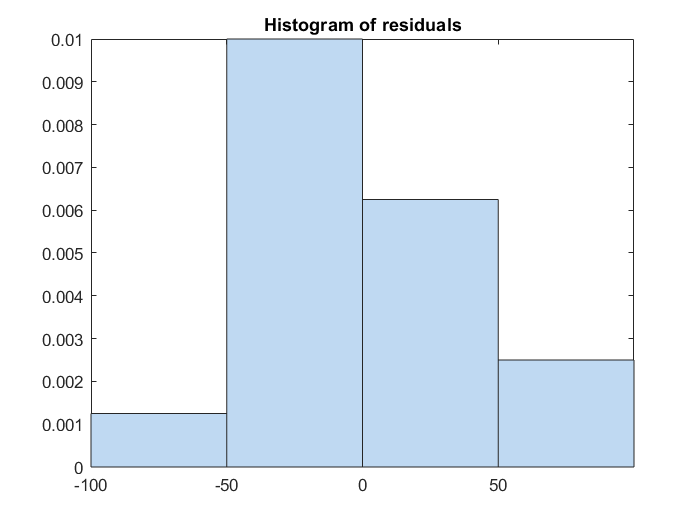

plotResiduals(mdl3) % plotResiduals to plot the residuals

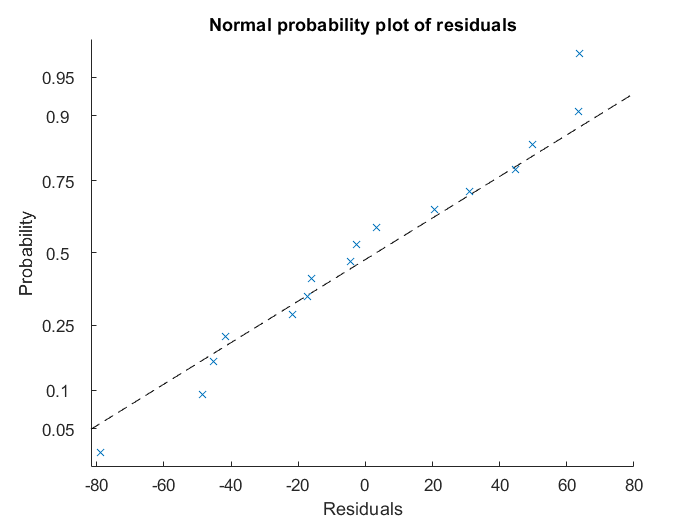

plotResiduals(mdl3,'probability')

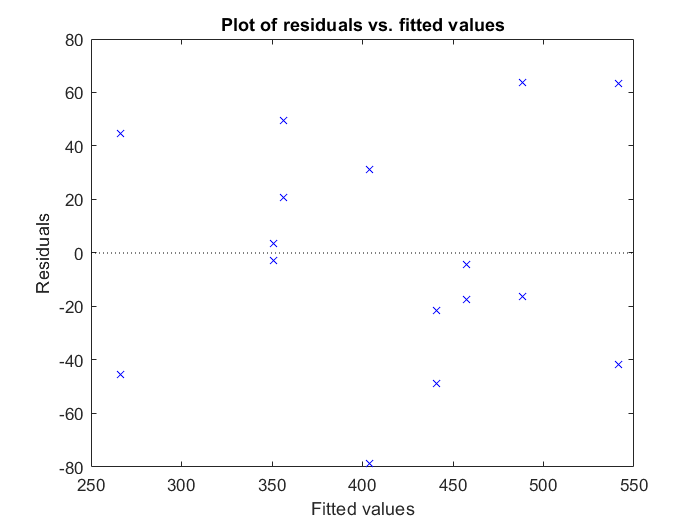

plotResiduals(mdl3,'fitted') % What we want to see from the fitted

% residuals plot is an "even" spread of the data across the domain


Step 6.6. Prediction Profiler

Use this for part b.

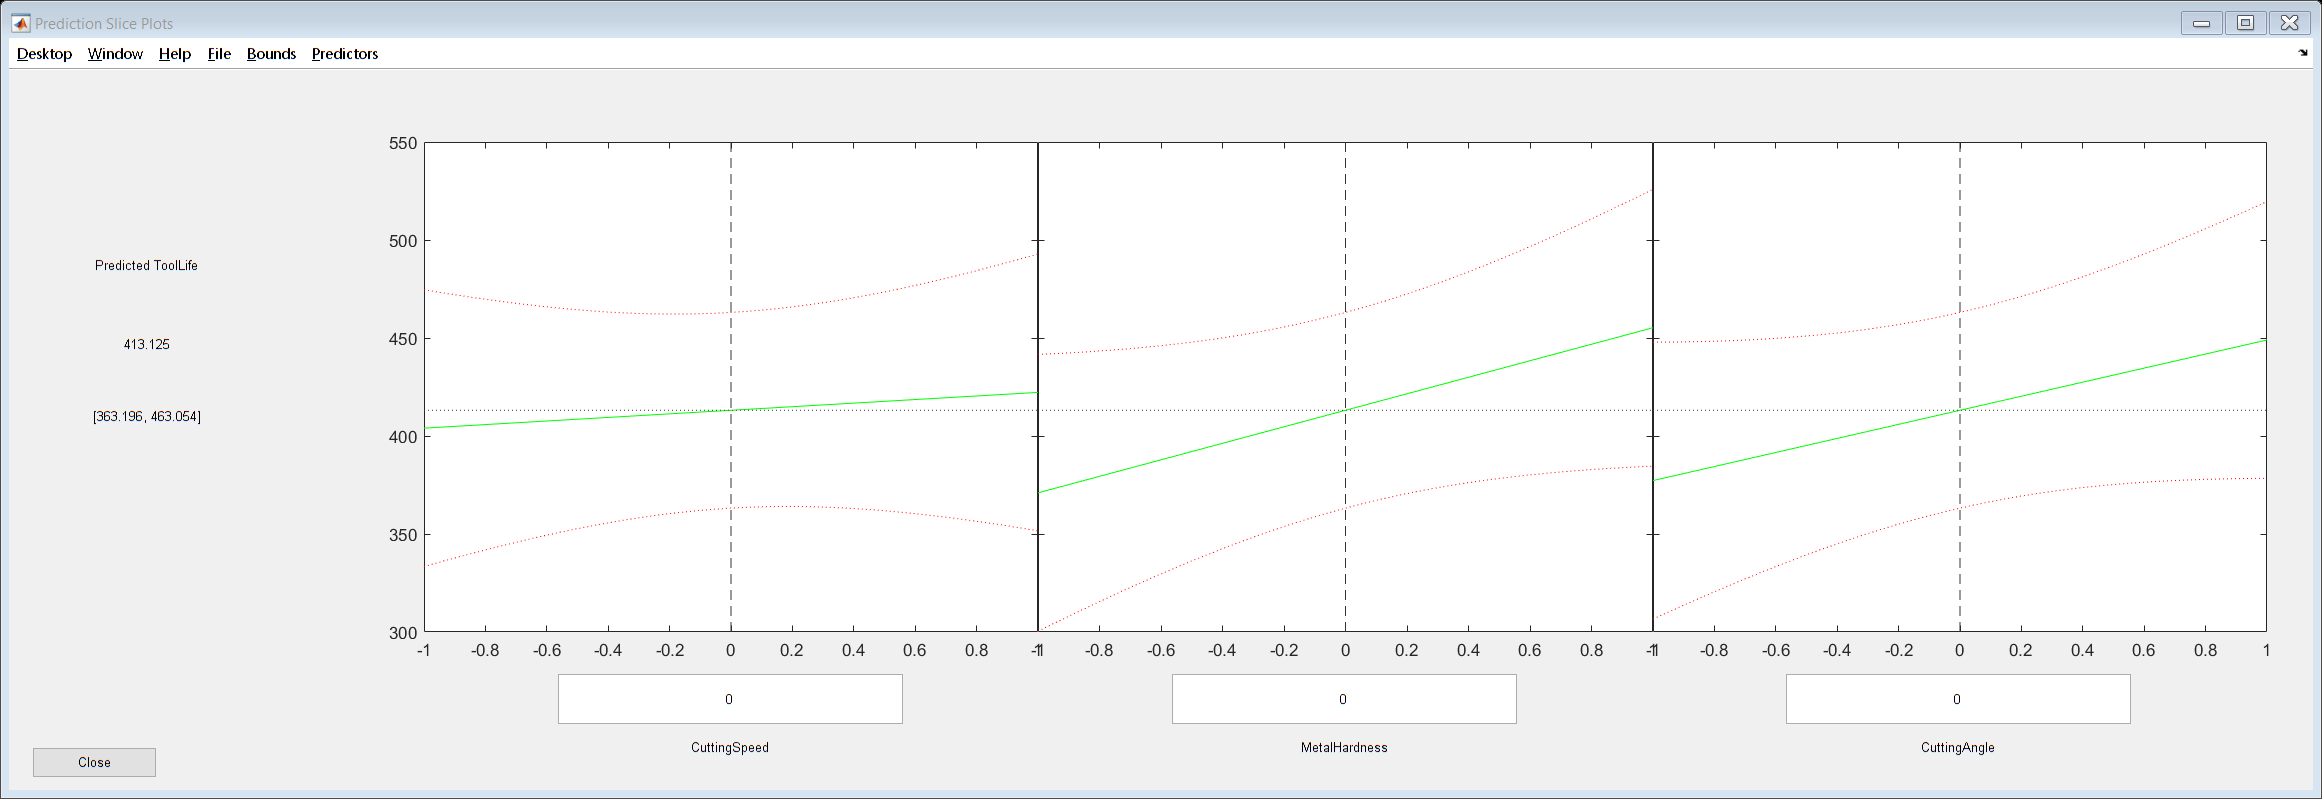

% Plot a prediction profiler
plotSlice(mdl3) 